clf;
homedir='/Volumes/Users/homes/Edita/Stats';

dirNameForFileName=strrep(homedir,'/','-slash-'); %if the dirName is in fact a path containing several directories, we substitute any / to the string -slash- as / is not a valid file name character
dirNameForFileName=strrep(dirNameForFileName,'\','-slash-');

delimiter='\t';
startRow = 2;

data=dir('Sorted_halflife_density.csv');
data = readtable(data.name);

all=data(1:110,1:9);

all_sorted=sortrows(all,5,"descend");
[sd,r]=sortrows(all,5,'descend');
region_names=all_sorted(:,1);
region_names=table2array(region_names);
region_names_cat=categorical(region_names);


region_area=all_sorted(:,8);
region_area=table2array(region_area);
region_area_cat=categorical(region_area);

mean_data=all_sorted(:,5);
mean_data=table2array(mean_data);
mean_data=mean_data(~isnan(mean_data));

subplot(2,1,1)
plot=scatter(region_names_cat,mean_data,'o','filled')

plot =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×110 categorical]
              YData: [1×110 double]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


%ylim([0;10])
%Get the CategoricalRuler from the axes in which 
%the scatter plot is located
ax = ancestor(plot, 'axes');
xruler = ax.XAxis;
% Get the Categories as listed on the ruler
cats = xruler.Categories;
% Shuffle the Categories and update the ruler
xruler.Categories = cats(region_names_cat);
x=[1:110]

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


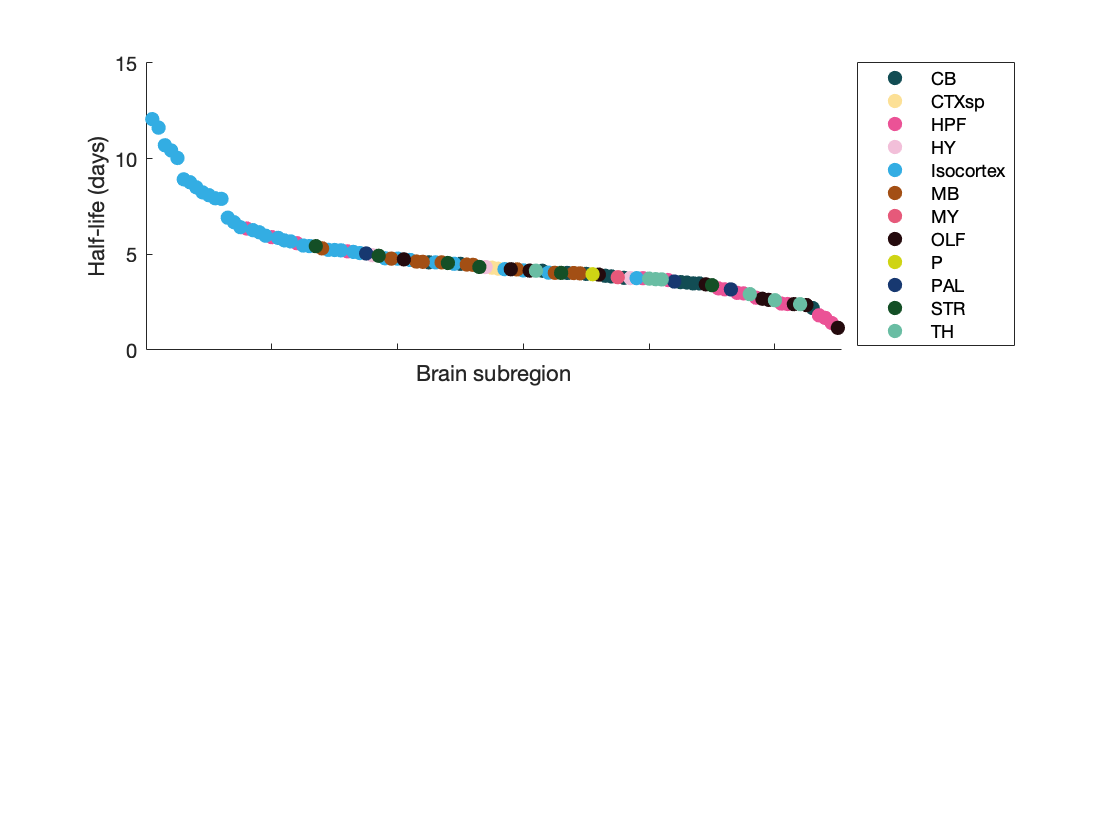



c=[0.07 0.3 0.33; 0.99 0.88 0.59; 0.92 0.32 0.59; 0.95 0.75 0.85; 0.2 0.68 0.89; 0.64 0.31 0.08; 0.9 0.35 0.48; 0.14 0.04 0.05; 0.81 0.83 0.08; 0.09 0.22 0.44; 0.08 0.31 0.15; 0.41 0.74 0.64];
gscatter(x,mean_data,region_area_cat,c,'.',20)
ylim([0;15])
xlim([0;110.5])
xticklabels([])
box('off')
ylabel('Half-life (days)')
xlabel('Brain subregion')
legend("Location",'bestoutside')
hold off